% dq/DqQ transformation matrices


## p/angle controller


k_d_vsm=70

k_d_vsm = 70

H_vsm = 3

H_vsm = 3

T_vsm = tf([omega_nom/(2*H_vsm*x_sys)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*x_sys)])

T =
 
          53.3
  --------------------
  s^2 + 11.67 s + 53.3
 
Continuous-time transfer function.
Model Properties



zeta_vsm = k_d_vsm/H_vsm*sqrt(2*H_vsm*x_sys/omega_nom)

zeta_vsm = 3.1961

nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))

nf_vsm = 7.3005

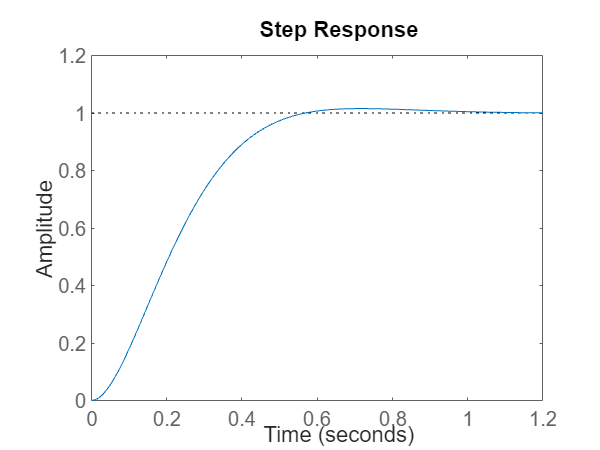

step(T_vsm)

## q controller droop


ki_q

ki_q = 314.1593

k_p_q_vsm = -0.05

k_p_q_vsm = -0.0500


% open loop

%closed loop 
T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])

T_q_vsm =
 
   -14.74
  ---------
  s + 299.4
 
Continuous-time transfer function.
Model Properties



%open loop Q_grid -> delta V_d_ref
T_e_vsm = tf([ki_q*k_p_q_vsm],[1 ki_q])

T_e_vsm =
 
   -15.71
  ---------
  s + 314.2
 
Continuous-time transfer function.
Model Properties


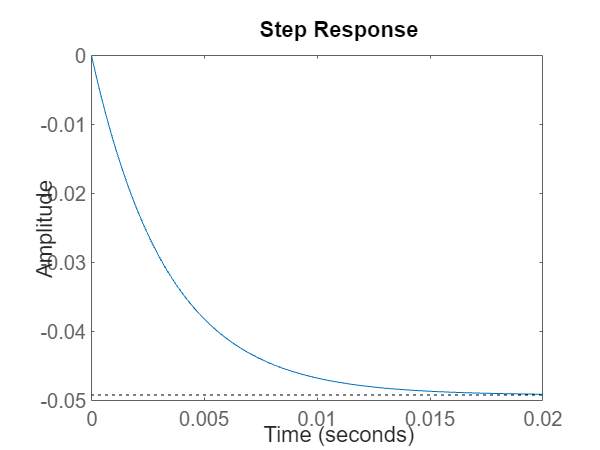


step(T_q_vsm)

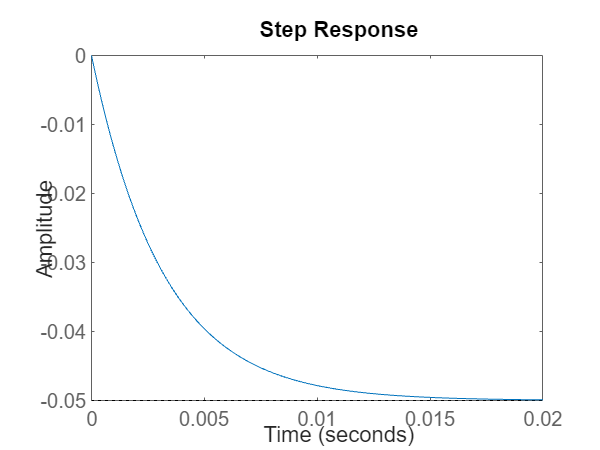

step(T_e_vsm)

## current control

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


ti = 5/f_sw

ti = 0.0017

G_plant = 1/(s*l_f+r_f)

G_plant =
 
           1
  -------------------
  0.1056 s + 0.005279
 
Continuous-time transfer function.
Model Properties


kp = l_f/ti

kp = 62.2908

ki = r_f/ti

ki = 3.1145

G_cc = (kp*s+ki)/s

G_cc =
 
  62.29 s + 3.115
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_cc = G_plant*G_cc/(1+G_plant*G_cc)

T_cc =
 
         6.577 s^3 + 0.6577 s^2 + 0.01644 s
  ------------------------------------------------
  0.01115 s^4 + 6.578 s^3 + 0.6577 s^2 + 0.01644 s
 
Continuous-time transfer function.
Model Properties



tf2ss([kp ki], [1 0])

ans = 0

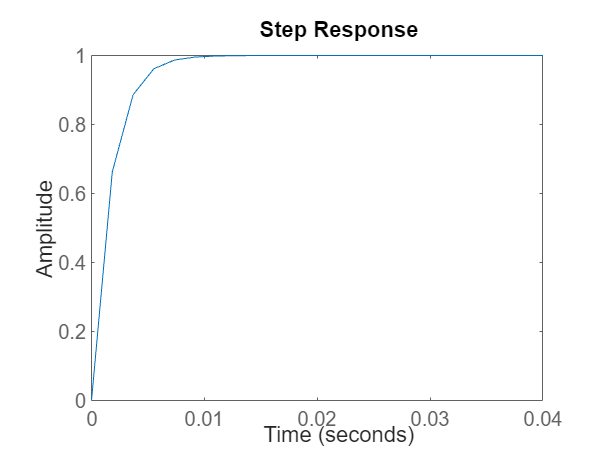


step(T_cc)

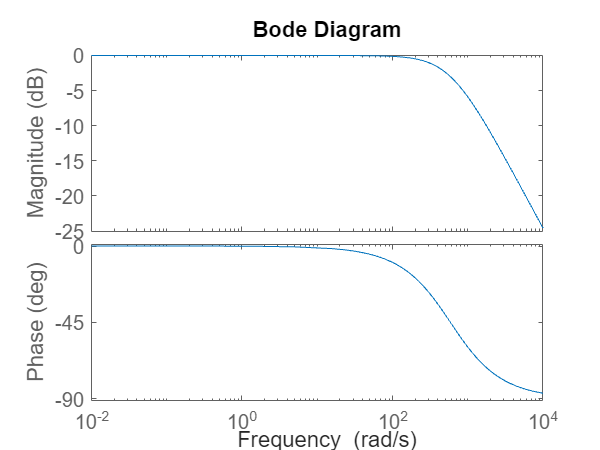

bode(T_cc)

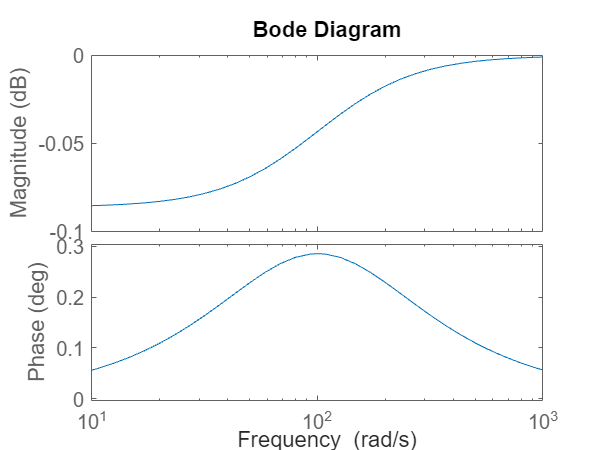

bode(((0.01*s+1)/0.01)/(1+(0.01*s+1)/0.01))     

## voltage control



z = 20

z = 20

asind((1-ti*z)/(1+ti*z)) % phase margin

ans = 69.1356

omega_c_vc = sqrt(z/ti)

omega_c_vc = 108.6278

k_vc = c_f*omega_c_vc

k_vc = 8.2231


%open
G_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2

G_vc =
 
  2.338e05 s + 4.676e06
  ---------------------
      s^3 + 590 s^2
 
Continuous-time transfer function.
Model Properties


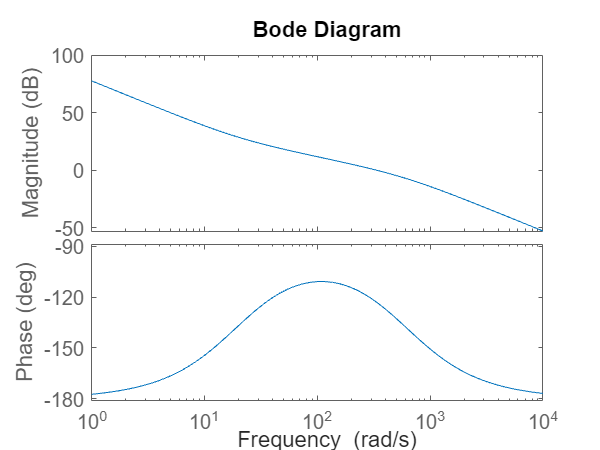

bode(G_vc)

% closed
T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)

T_vc =
 
          2.338e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
  -----------------------------------------------------------
  s^6 + 1180 s^5 + 5.819e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
 
Continuous-time transfer function.
Model Properties


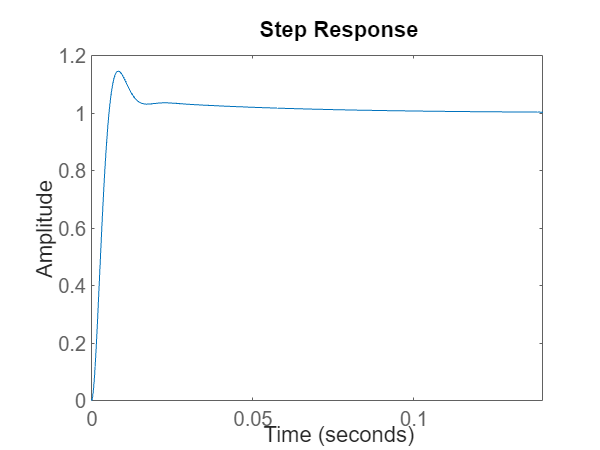

    step(T_vc)

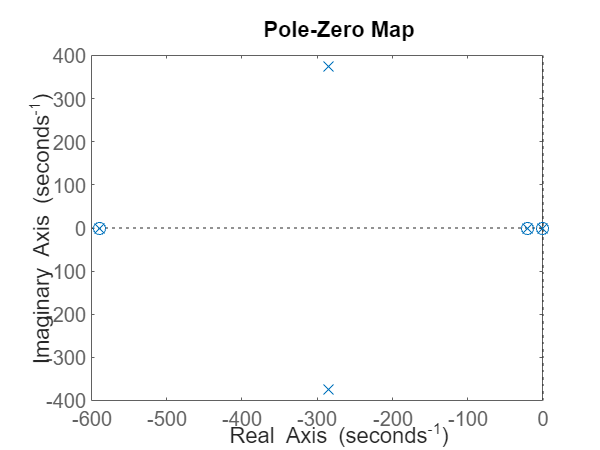

    pzmap(T_vc)

% negative 1 is steady state wind power pu
% cross over frequency is 20 rad/s
    zigma_dc = 2*l_f*(1)/(3*1^2)

zigma_dc = 0.0704

k0 = 1.5

k0 = 1.5000

G_dc_pre =-k0*2/c_dc*(zigma_dc*s+1)/(s^2*(0.01*s+1)) 

G_dc_pre =
 
  -31.68 s - 450.1
  ----------------
   0.01 s^3 + s^2
 
Continuous-time transfer function.
Model Properties


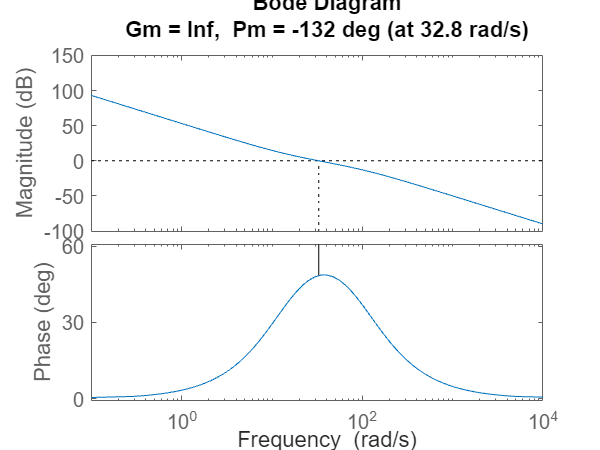

margin(G_dc_pre)

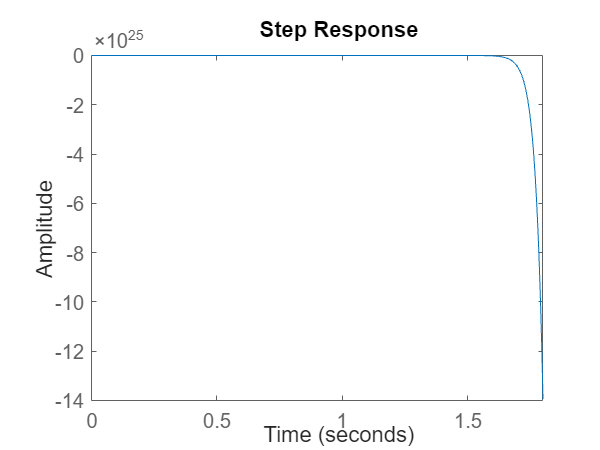

step(G_dc_pre/(1+G_dc_pre))


n0 = 1/(10^(-13/20));

a = 50;
asind((a-1)/(a+1)) % phase margin

ans = 73.9011

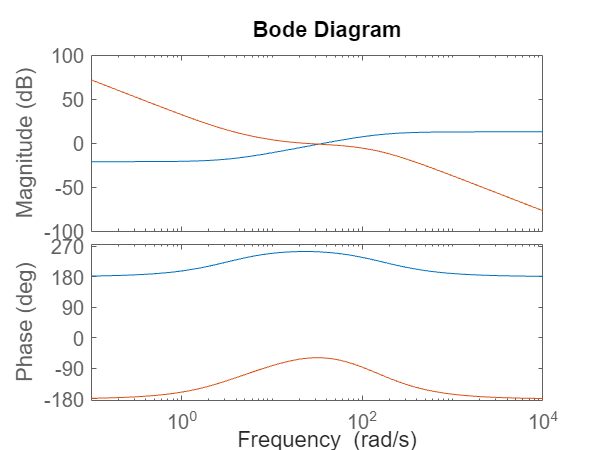

p = sqrt(a)*23;
N = -n0*(s+p/a)/(s+p);
bode(N,N*G_dc_pre)

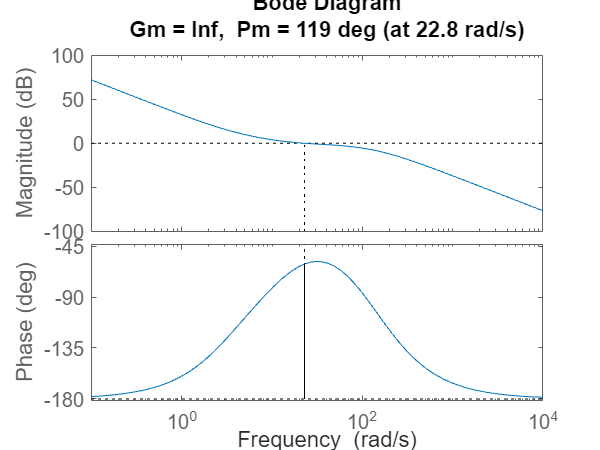

margin(N*G_dc_pre)

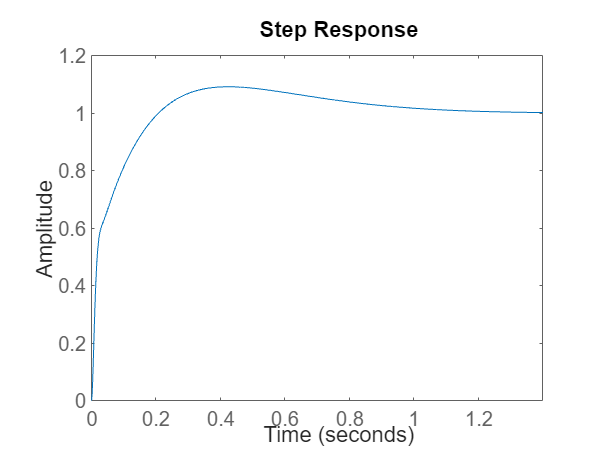

step(G_dc_pre*N/(1+G_dc_pre*N))